Written by Brandon Swartz

For Dr. Sharon Weiss' ECE 6303 Nanophotonics course, Spring 2026

## Section 1. Set-up

Run this section at the beginning of class to make sure everything everything is set-up correctly. Let Brandon know if you get any errors.

To run a section, press "Ctrl + Enter" or click the "Run Section" button in the LIVE EDITOR tab.

#### Clear the matlab workspace and add functions to path

clc; clearvars; close all
cd(fileparts(matlab.desktop.editor.getActive().Filename))
addpath('utils')
addpath('textures')
addpath('reticolo')
gcp;

#### Define the materials used for the metasurface

I've entered material properties for a metasurface with silicon pillars on a sapphire (crystalline Al2O3) substrate. You don't need to change anything here.

Only the indices of refraction are actually used in the script. The material names and notes are used when saving simulated data.

% Background material
mat_background = "air";
n_background = 1;
note_background = "";

% Pillar material
mat_pillar = "Si";
n_pillar = 3.427;
note_pillar = "Si at 4 um, refractiveindex.info/?shelf=main&book=Si&page=Franta-300K";

% Substrate material
mat_substrate = "Al2O3";
n_substrate = 1.675;
note_substrate = "Al2O3 at 4 um, refractiveindex.info/?shelf=main&book=Al2O3&page=Malitson-o";

## Section 2. Meta-atom parameters

We are going to simulate some simple metasurfaces composed of cylindrical pillars. To define the meta-atoms, we need to specify the height, diameter, and pitch of the pillars. We can make metasurfaces with complex behavior by varying the diameter of the meta-atoms across the surface; in order to facilitate this, we will simulate meta-atoms with a range of different diameters, but all meta-atoms will have the same height and pitch.

We'll also specify the wavelengths of light for the simulations. For no reason in particular, I've chosen to use the mid-wave infrared (3 to 5 μm) for this activity. We'll design a metasurface to operate on 4 μm illumination, and we'll simulate what happens when illumination deviates from the design wavelength.

### Set the meta-atom height and pitch to simulate.

pitch = 2;              % μm, meta-atom pitch
height = 2.6;           % μm, meta-atom height

% Pillar Width or Diameter Sampling
num_widths = 50;       % Number of different pillar widths to simulate
min_width = 0.1 * height;  % μm, Minimum pillar width
max_width = 0.7 * pitch;   % μm, Maximum pillar width

% Wavelength Sampling
num_wavelengths = 5;  % Number of different wavelengths to simulate
min_wavelength = 3;    % μm, Minimum wavelength to simulate
max_wavelength = 5;    % μm, Maximum wavelength

pillar_shape = "circle";  % "circle" or "square". This is only used as a label when saving data, which is my standard practice but is not necessary for this activity.
type = "pillars";         % "pillars" or "holes"
corners = "round";        % "round" for circular pillars, "square" for square pillars. This is what actually determines the pillar shape.

The meta-atom simulations will be done using [*RETICOLO software for grating analysis*](https://doi.org/10.48550/arXiv.2101.00901), which is a MatLab implementation of rigorous coupled wave analysis (RCWA). RCWA can be interpretted as an extension of the transfer matrix method (TMM) for stacks of 2D gratings. In contrast with homogenous thin films simulated with TMM, 2D grating layers exhibit scattering in-plane into discrete in-plane modes. RCWA involves first solving for the in-plane mode shapes (i.e. finding solutions to Maxwell's equations in each layer with periodic boundary conditions), then constructing scattering matrices which describe how light propagates in each mode and each layer.

Dr. Raymond Rumpf from the University of Texas El Paso has [great course materials for learning more about RCWA](https://empossible.net/academics/emp5337/) (and many other numerical methods) if you are interested. The following figures are from [his lecture 7a slides](https://empossible.net/wp-content/uploads/2019/08/Lecture-7a-RCWA-Formulation.pdf). However, it is not necessary to understand exactly how RCWA works for the purpose of this activity.

#### Example grating layer for RCWA. Each layer must be homogenous in z and periodic in x and y.

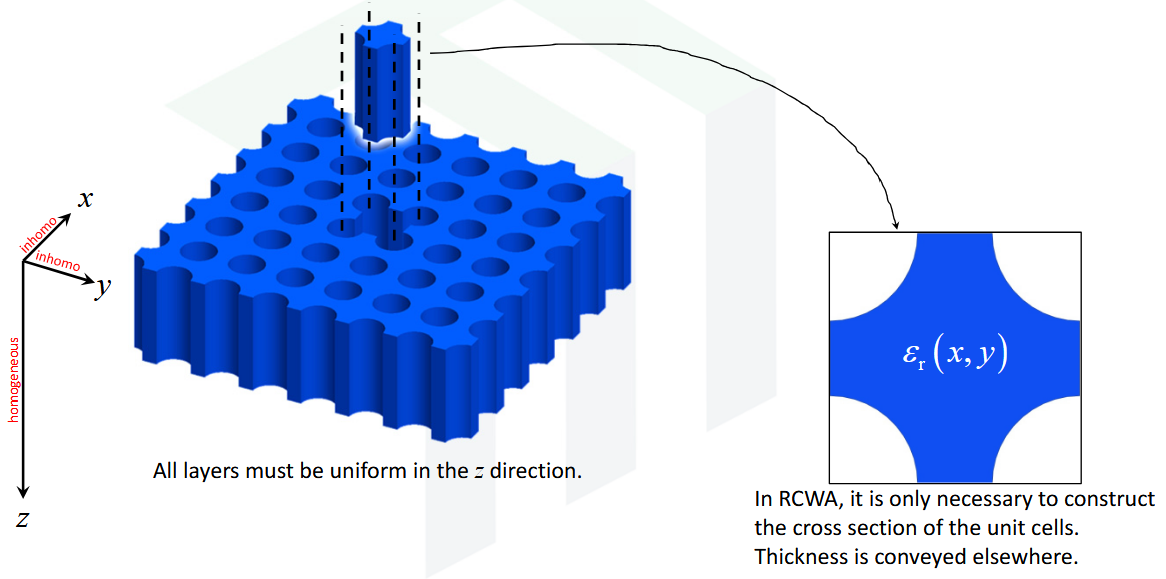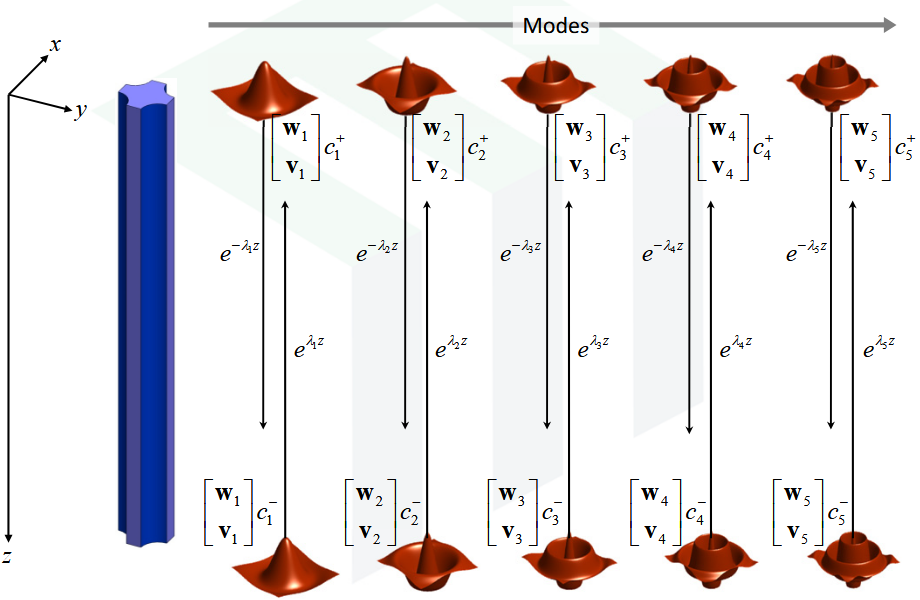

#### Any number of these 2D layers can be stacked to form complex multilayer structures.

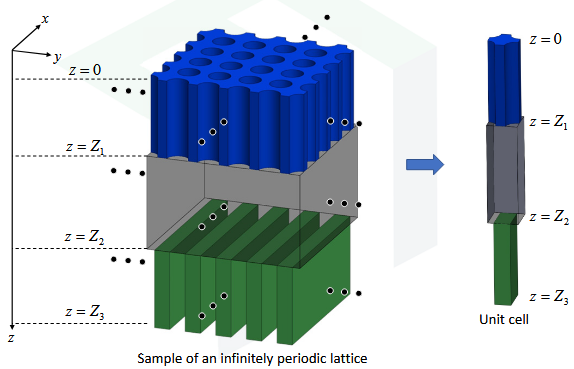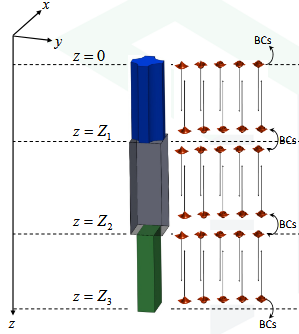

## Section 3. Visualize the smallest and largest pillar

Create a 3D visual of the pillars, to check that everything is set up correctly.

The geometry of the meta-atoms is passed to RETICOLO in 2 specially formatted cell arrays: a "texture" array that defines the 2D grating in each layer, and a "profile" array that specifies the thicknesses and order of the layers. I've already written a series of functions to create the correctly formatted texture and profile arrays for various simple unit cells. We'll use the "square" function, which can define square or circular pillars (in RETICOLO, squares and circles have a very similar definition. If you'd like to understand more, the texture and profile arrays are described clearly in the RETICOLO documentation (included in this directory).

To make sure the geometry is entered and formatted correctly, I pass the texture and profile arrays to plot_texture, which uses some intermediate results from RETICOLO to create a 3D visualization of the meta-atoms.

figure(Position=[0,0,600,350])
tiledlayout(1, 2, "TileSpacing", "tight", "Padding", "tight");

% Smallest Pillar
[texture_small, profile] = square(n_substrate, n_pillar, n_background, height, min_width, corners, type);
nexttile
title('Smallest Pillar')
plot_texture(texture_small, profile, [pitch, pitch])

% Largest Pillar
[texture_large, profile] = square(n_substrate, n_pillar, n_background, height, max_width, corners, type);
nexttile
title('Largest Pillar')
plot_texture(texture_large, profile, [pitch, pitch])
clear texture_small texture_large profile

## Section 4. Simulate the complex transmittance of each meta-atom

Prepare to loop through each pillar size and each wavelength

wavelength = linspace(min_wavelength, max_wavelength, num_wavelengths);
wavelength_lim = [min_wavelength, max_wavelength, num_wavelengths];
width = linspace(min_width, max_width, num_widths);
width_lim = [min_width, max_width, num_widths];

progress_bar_step = 1/num_widths;

trans_data = zeros(num_wavelengths, num_widths, 2);

#### Simulate meta-atoms in loop

progress = 0;
fig = uifigure;
fig.Position(3:4) = [460 160];
progress_bar = uiprogressdlg(fig, 'Title','Simulating Meta-atoms','Message','Starting parallel pool');

for j1 = 1:num_widths
    width_j = width(j1);
    parfor k = 1:num_wavelengths
        [texture, profile] = square(n_substrate, n_pillar, n_background, height, width_j, corners, type);
        [trans, ~] = RCWA_simple(wavelength(k), texture, profile, "fourier_modes", 3, "period", pitch);
        trans_data(k,j1,:) = [real(trans) imag(trans)];
    end

    progress = progress + progress_bar_step;
    progress_bar.Value = min(progress, 1);
    progress_bar.Message = sprintf('Progress: % .2f %%', 100*progress);
    drawnow
end
close(fig)  % Close the progress bar
clear progress_bar_step progress progress_bar fig width_j texture profile trans j1 k

I normally save my meta-atom data in specially formatted mat files so I can use it in other workflows. That isn't really necessary here. If you want to save the data, uncomment the following function call.

% WriteMat(pillar_shape, "MWIR", "micron", "RealImag", ...
%     "Material", mat_pillar, "pillar", n_pillar, note_pillar, ...
%     "Material", mat_substrate, "substrate", n_substrate, note_substrate, ...
%     "Material", mat_background, "background", n_background, note_background,...
%     "Param", "wavelength", wavelength_lim, "",...
%     "Param", "width", width_lim, "Width of pillar",...
%     "Constant", "height", height, "",...
%     "Constant", "pitch", pitch, "",...
%     "Data", "transmission_bottom_0_0", trans_data, "[Real Imag] of transmitted light",...
%     "Notes", "Simulated with Reticolo, last update 12/2013\n")

The transmission data is complex, but is stored as a (Nw, Nd, 2) matrix of the real and imaginary components so that the saved data is easier to load in other software. Within MatLab, its generally easier to work directly with the complex values, so we will convert the data back to a (Nw, Nd) matrix of complex values.

trans_data = complex(trans_data(:, :, 1), trans_data(:, :, 2));

Also extract the phase and transmittance from the complex transmission. Transmittance is the transmitted intensity, which is the amplitude of the transmitted field squared.

The absolute phase is not critical; only the relative phase difference between meta-atoms matters. To make plots a little cleaner, shift the phase to be relative to the smallest pillar at the center wavelength and unwrap the phase so its easier to see the magnitude of the relative phase delay.

transmittance = abs(trans_data).^2;
phase = angle(trans_data);

center_index = ceil(num_wavelengths/2);
center_wavelength = wavelength(center_index);

phase = unwrap(phase, [], 1);            % Unwrap the phase in the wavelength dimension
phase = unwrap(phase, [], 2);            % Unwrap the phase in the diameter dimension
phase = phase - phase(center_index, 1);  % Shift the phase so that it is relative to the smallest pillar 

## Section 5. Plot the phase and transmittance of the meta-atoms at the center wavelength

colors = jet(num_wavelengths);  % A list of colors I will use to plot different wavelengths later on. I define it here so I can always use the same color for the center wavelength curve.

% Create a 2 tile figure
fig = figure;
fig.Position(3:4) = [400, 400];
tl = tiledlayout(2, 1, "TileSpacing", "tight", "Padding", "tight");
title(tl, sprintf("Transmission at %g μm", center_wavelength), FontWeight='bold', FontSize=16);

% In the first tile, plot the phase of each meta-atom
ax_phase = nexttile;
phase_center = phase(center_index, :);
plot(width, phase_center, Color=colors(center_index, :))

% In the second tile, plot the transmittance
ax_amp = nexttile;
plot(width, transmittance(center_index, :), Color=colors(center_index, :))

phase_amplitude_plot_labels(ax_phase, ax_amp)

Hopefully this plot shows the phase increasing smoothly from 0 to 2π without any large dips in the transmittance. If the phase delay doesn't reach 2π or if there any many sharp resonances, think about how you could change the pillar height and pitch to improve the result.

It is sometimes okay to have a small number of narrow resonances, because you can choose to just not use the pillar diameters that have resonances at the design wavelength. Let's try to automatically detect and remove such resonances, without decreasing the phase coverage of the library. This will work creating a new phase and width vector where the phase has been made monotonically increasing by removing the sections where the phase is decreasing due to a resonance.

% Check for areas with decreasing phase
width_increasing = width;           % This will hold a vector of the pillar widths where the phase is increasing.
phase_increasing = phase_center;    % This will hold a vector of the phases where the phase is increasing.

phase_decreasing = diff(phase_increasing) < 0;
if any(phase_decreasing)
    % Prepare to add an annotation to the plot
    lim = ylim(ax_phase);
    hold(ax_phase, "on")
    hold(ax_amp, "on")
    
    % Find the rising and falling edges of phase_decreasing
    edges = find(diff(phase_decreasing)) + 1;
    while ~isempty(edges)
        local_max_width = width_increasing(edges(1));
        local_max_phase = phase_center(edges(1)) + eps(phase_center(edges(1)));
        return_to_max = interp1(phase_center(edges(2):end), width_increasing(edges(2):end), local_max_phase, 'linear', -1);
        if return_to_max > 0
            % The phase has a dip between local_max_width and return_to_max
            good_idx_pre = width_increasing <= local_max_width;  % The elements before the dip
            good_idx_post = width_increasing > return_to_max;    % The elements after the dip
            width_increasing = [width_increasing(good_idx_pre), return_to_max, width_increasing(good_idx_post)];
            phase_increasing = [phase_increasing(good_idx_pre), local_max_phase, phase_increasing(good_idx_post)];
            
            % Mark the deleted region on the plot
            fill(ax_phase, [local_max_width, local_max_width, return_to_max, return_to_max],...
                 [lim fliplr(lim)], 'r', FaceAlpha=0.2, EdgeColor='none')
            fill(ax_amp, [local_max_width, local_max_width, return_to_max, return_to_max],...
                 [lim fliplr(lim)], 'r', FaceAlpha=0.2, EdgeColor='none')

        else
            % The phase has a dip starting at local_max_width and it never recovers back to its starting value
            good_idx_pre = width_increasing <= local_max_width;  % The elements before the dip
            width_increasing = width_increasing(good_idx_pre);
            phase_increasing = phase_increasing(good_idx_pre);

            % Mark the deleted region on the plot
            fill(ax_phase, [local_max_width, local_max_width, max_width, max_width],...
                 [lim fliplr(lim)], 'r', FaceAlpha=0.2, EdgeColor='none')
            fill(ax_amp, [local_max_width, local_max_width, max_width, max_width],...
                 [lim fliplr(lim)], 'r', FaceAlpha=0.2, EdgeColor='none')
        end
        
        phase_decreasing = diff(phase_increasing) < 0;
        edges = find(diff(phase_decreasing)) + 1;
    end
end

Finally, we can check the phase coverage of the library. I.e. Does the library of meta-atoms have a phase range of at least 2π between the smallest and largest pillar.

% Try to find the pillar diameter where the phase delay is 2*pi
if max(phase_increasing) < 2*pi
    text(ax_phase, min_width, max(phase_increasing),...
         sprintf("The maximum phase\nis only %.3gπ!", max(phase_increasing)/pi),...
         VerticalAlignment='top')
else
    yline(ax_phase, 2*pi, ':')
    d_max = interp1(phase_increasing, width_increasing, 2*pi);
    xline(ax_phase, d_max, ':')
    xline(ax_amp, d_max, ':')

    % width_increasing and phase_increasing are just used to create a
    % lookup table between phase and geometry. The phase values above 2pi
    % will be never by used and can be deleted.
    good_idx = width_increasing < d_max;
    width_increasing = [width_increasing(good_idx) d_max];
    phase_increasing = [phase_increasing(good_idx) 2*pi];
end
clear fig tl ax_phase ax_amp phase_decreasing lim edges local_max_width local_max_phase return_to_max good_idx_pre good_idx_post good_idx

### Discussion:

- Is this meta-atom library good enough?

- If not, what can we control to try to find a better meta-atom library?

- Can you spot any Fabry-Perot effects? What influences the intensity of the FP oscillations?

## Section 6. Simulate the fields in a meta-atom

### Change the wavelength_to_plot and width_to_plot variables to any wavelength and pillar width that you want to simulate.

wavelength_to_plot = (min(wavelength) + max(wavelength)) / 2;
width_to_plot = min(width);  %% %% %% Change this to simulate different pillars %% %% %%

% Simulation settings
fourier_modes = [6, 6];  % The number of fourier modes to include in the calculations. [6, 6] means order -6 to +6 in x and -6 to +6 in y.
parm = res0;          % loads the default parameters
parm.sym.x = 0;       % x-direction mirror symmetry plane (i.e. meta-atoms are symmetric about x=0)
parm.sym.y = 0;       % y-direction mirror symmetry plane
parm.sym.pol = 1;     % polarization, TE = 1, TM = -1
parm.res1.champ = 1;  % Uses higher accuracy algorithm for calculating EM fields

x = linspace(-pitch/2, pitch/2, 31);  % The sampling points along the x and y axes for the field plots

Generate the texture and profile arrays that define the meta-atom geometry. Texture contains information about each 2D layer. Profile dictates the order and thickness of each layer. Normally, I set the thickness of the air layer and substrate layer to 0, which essentially means that the boundary conditions on the air and substrate are applied, but the sim does not include the trivial propagation through these homogenous layers. However, for this section we *do* want to simulate into the air and substrate a bit so we can visualize the waves approaching and departing from the pillars.

[texture, profile] = square(n_substrate, n_pillar, n_background, height, width_to_plot, corners, type);
profile{1}(1) = 1;      % Air layer thickness. Add space to the 1st and 3rd layer for plotting purposes
profile{1}(3) = 1;      % Substrate layer thickness.

% Create animated plots of the electric field.
plot_e_fields(wavelength_to_plot, pitch, texture, profile, parm, fourier_modes, x, width_to_plot, height)
clear wavelength_to_plot width_to_plot fourier_modes parm texture profile

### Discussion:

- Simulate a non-resonant meta-atom. What behavior do you observe? How do you know it is non-resonant?

- Simulate a resonant meta-atom. What behavior do you observe? How do you know it is resonant?

## Section 7. Design a simple metasurface

We will represent the metasurface as a matrix where each element of the matrix corresponds to 1 meta-atom on the surface.

There is no strict requirement to simulate the metasurface with the same sampling pitch as the meta-atom pitch, but it is a convenient choice when simulating small metasurfaces.

#### Metasurface parameters and sampling coordinate matrices

diameter_aperture = 1000;         % μm, diameter of metasurface
focal_length = 1000;     % μm, designed focal length at the center wavelength

numel_metasurface = ceil(diameter_aperture / pitch);       % number of sample points needed to store metasurface
numel_sim = 2 ^ (ceil(log2(numel_metasurface)) + 1);  % number of sample points used for the ASM propagation

x = pitch * (-numel_metasurface/2:numel_metasurface/2-1);  % x coordinate of each sampling point
x_squared = x.^2;
r_squared = x_squared + x_squared';             % r^2 coordinate of each sampling point

aperture = r_squared <= (diameter_aperture / 2)^2;       % bool matrix that represents the clear aperture of the metalens

### Derive a diffraction limited metasurface phase profile. We'll do this together as a class.

phase_ideal = -2*pi/center_wavelength * sqrt(r_squared + focal_length^2);
center_index = floor(numel_metasurface / 2) + 1;
phase_ideal = phase_ideal - phase_ideal(center_index, center_index) + pi - eps(4*pi);
phase_ideal = wrapToPi(phase_ideal);
phase_ideal(~aperture) = nan;

trans_ideal = 1 * exp(1i * phase_ideal);

#### Plot the ideal metalens phase

figure(Position=[0, 0, 600, 300])
tiledlayout(1, 2, TileSpacing='tight', Padding='tight')

ax = nexttile;
center_index = floor(numel_metasurface / 2) + 1;
plot(x(center_index:end), phase_ideal(center_index, center_index:end))
axis square
axis([0, 200, -1.1*pi, 1.1*pi])
ax.YTick = [-pi 0 pi];
ax.YTickLabel = arrayfun(@pi_string, ax.YTick / pi, 'UniformOutput', false);
title('Plot of φ_{ideal}(r)')
xlabel('r, μm')
ylabel('Phase')
format_plot

nexttile
im = imshow(phase_ideal, [-pi, pi], Colormap=hsv, XData=[x(1) x(end)], YData=[x(1) x(end)]);
set(im, 'AlphaData', aperture)
axis image
cbar = colorbar;
cbar.Ticks = [-pi 0 pi];
cbar.TickLabels = arrayfun(@pi_string, cbar.Ticks / pi, 'UniformOutput', false);
cbar.Label.String = 'Phase';
title('2D Representation')
xlabel('x, μm')
axis on
box off
format_plot

#### Use the relationship between meta-atom diameter and phase from section 5 to calculate the diameter of the meta-atoms in the metasurface.

diameter_atoms = interp1(phase_increasing-pi, width_increasing, phase_ideal);
figure(Position=[0,0,600, 300])
tiledlayout(1, 2, TileSpacing='tight', Padding='tight')

nexttile
plot(x(center_index:end), diameter_atoms(center_index, center_index:end))
axis square
xlim([0, 200])
title('Meta-atom Diameters')
xlabel('r, μm')
ylabel('Diameter, μm')
format_plot

nexttile
im = imshow(diameter_atoms, [], Colormap=jet, XData=[x(1) x(end)], YData=[x(1) x(end)]);
set(im, 'AlphaData', aperture)
axis image
cbar = colorbar;
cbar.Label.String = 'Diameter, μm';
title('2D Representation')
xlabel('x, μm')
axis on
box off
format_plot
clear cbar im ax

## Section 8. Simulate PSF of metasurface at the center wavelength

Next, we'll simulate how the metalens focuses light, by simulating the point spread function of the metalens. Starting with some wavefront on the metalens, we want to know (a) how does the metalens change the wavefront and (b) how does the wavefront propagate from the metalens plane to the focal plane. For brevity, I'll do the derivation for a 1D metasurface, but the result can be seemlessly extended to the 2D case.

The first step is easy, thanks to our local metasurface approximation. Each meta-atom locally modulates the wavefront at a single point. Defining $U_{\;} \left(x,0^{-\;} \right)$ is the field immediately before the metasurface and $t\left(x\right)$ is the complex transmittance of the metasurface, the field after the metasurface is simply $U\left(x,0^+ \right)=t\left(x\right)U\left(x,0^- \right)$.

Next, we have to calculate how light propagates from $z=0^+$ to $z=z_f$, the focal plane. I have slides that walk through this step-by-step if anyone gets lost.

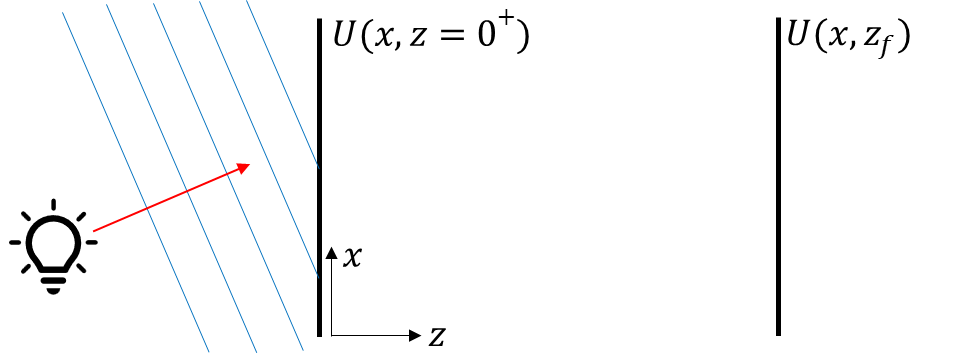

To do this, we're going to use the angular spectrum method, which is a Fourier optics tool for calculating light propagation between planes.

To understand how this works, first consider the case where $U\left(\mathit{\mathbf{r}}\right)$ is just a plane wave, $\textrm{𝑈}\left(\textrm{𝐫}\right)={\textrm{𝐴𝑒}}^{\left(\textrm{𝑖𝐤}\cdot \textrm{𝐫}\right)} ={\textrm{𝐴𝑒}}^{\left({\textrm{𝑖k}}_x x+{\textrm{ik}}_z z\right)}$. As z increases, the wave accumlates phase due to the phase term $e^{{\textrm{ik}}_z z}$. Therefore, for a plane wave: $U\left(x,z\right)=U\left(x,0^+ \right)e^{{\textrm{ik}}_z z}$.

Next, consider the case where $U\left(\mathit{\mathbf{r}}\right)$ is the sum of multiple plane waves travelling in different directions. We can express $U\left(\mathit{\mathbf{r}}\right)$ as a summation or integral over all its plane wave components, and each plane wave component propagates forward exactly as :


$$\textrm{𝑈}\left(x,z\right)=\int_{-k}^k \textrm{𝐴}\left({\textrm{𝑘}}_x \right)e^{{\textrm{ik}}_x x} e^{{\textrm{ik}}_z z} {\textrm{dk}}_x ={\mathcal{F}}^{-1} {\left\lbrace \textrm{𝐴}\left({\textrm{𝑘}}_x \right)e^{{\textrm{ik}}_z z} \right\rbrace }_x$$
                    
$$8\ldotp 1$$



$$\textrm{𝑈}\left(x,0\right)=\int_{-k}^k \textrm{𝐴}\left({\textrm{𝑘}}_x \right)e^{{\textrm{ik}}_x x} {\textrm{dk}}_x ={\mathcal{F}}^{-1} {\left\lbrace \textrm{𝐴}\left({\textrm{𝑘}}_x \right)\right\rbrace }_x$$
                                 
$$8\ldotp 2$$


$\textrm{𝑈}\left(\mathit{\mathbf{r}},z\right)$ is just an (angular) inverse Fourier transform of $\textrm{𝐴}\left({\textrm{𝑘}}_x \right)e^{{\textrm{ik}}_z z}$. Thus, we can invert this equation to find the plane wave decomposition for any arbitrary wave. ***Any propagating wave can be expressed using plane wave decomposition. ***$\textrm{𝐴}\left({\textrm{𝑘}}_x \right)$ is called the *angular spectrum* of the propagating wave because it represents the (complex) amplitude of the plane waves travelling in different directions (i.e. angles).


$$\textrm{𝐴}\left({\textrm{𝑘}}_x \right)=\mathcal{F}{\left\lbrace U\left(x,0\right)\right\rbrace }_{k_x }$$
                                                                     
$$8\ldotp 3$$


To evaluate 8.1, we also need to express $k_z$ in terms of $k_x$, which we can do because $k_x^2 +k_z^2 =k^2$, where k is the magnitude of the wavevector $\left(k=\frac{2\pi }{\lambda }\right)$, which is a constant.


$$e^{{\textrm{ik}}_z z} =e^{\textrm{iz}\sqrt{k^2 -k_x^2 }}$$
                                                                                
$$8\ldotp 4$$


We can then plug 8.3 and 8.4 into 8.1 to get our final equation for $\textrm{𝑈}\left(x,z\right)$.


$$\textrm{𝑈}\left(x,z\right)={\mathcal{F}}^{-1} {\left\lbrace \mathcal{F}{\left\lbrace U\left(x,0\right)\right\rbrace }_{k_x } \cdot e^{\textrm{iz}\sqrt{k^2 -k_x^2 }} \right\rbrace }_x$$
                                  
$$8\ldotp 5$$


## Implemention

#### 1. Define the incident wavefront illuminating the metasurface. We'll do the simplest case, which is a normally incident plane wave.

% A normally incident plane wave is constant in-plane, so we can just represent it as a constant.
incident_wave = 1.; % Units are arbitrary power/area.

% It is convenient to set know total power in the incident wave, so we can
% calculate efficiency. The total energy is the sum of the intensity of the
% incident wave across the metasurface aperture.
incident_energy = sum(abs(incident_wave)^2 .* aperture, 'all');

#### 2. Use the meta-atom library simulated in section 4 to look up the transmission matrix of the metasurface designed in section 7.

% Look-up the meta-atom transmission using linear interpolation
ms_transmission = interp1(width, trans_data(center_index, :), diameter_atoms);

% Linear interpolation of complex values stored at (real, imag) can lead to
% error in the amplitude. The most robust solution is to separately interpolate
% the amplitude.
amplitude_accurate = interp1(width, abs(trans_data(center_index, :)), diameter_atoms);
ms_transmission = amplitude_accurate .* ms_transmission ./ abs(ms_transmission);

% Block light outside the clear aperture of the metasurface
ms_transmission = fillmissing(ms_transmission, 'constant', 0);

#### 3. Multiply the incident wavefront by the metasurface transmission matrix.

wave = incident_wave .* ms_transmission;  % Wave after the metasurface

#### 4. Perform a discrete Fourier transform (DFT) to get the angular spectrum of the wave right after the metasurface.

The above *wave* is sampled with spatial sampling pitch *pitch *(defined in section 2). After a DFT, the resulting *angular_spectrum *will be sampled with *k_pitch = *$\frac{2\pi }{n\cdot \textrm{pitch}}$, where *n* is the number of samples across one axis. Generally, to avoid numerial artifacts in the DFT, *n* needs to be larger than the minimum number of elements needed to represent the wave, which is achieved by zero-padding the wave matrix.

wave = zeropad(wave, numel_sim);    % Zero-pad to increase the size of the wave matrix
angular_spectrum = ifftshift(fft2(fftshift(wave)));  % Angular spectrum after the metasurface
k_pitch = 2 * pi / (numel_sim * pitch);  % Space between samples in k-space, 1/μm

#### 5. Multiply by the exact free space transfer function $e^{\textrm{iz}\sqrt{k^2 -k_x^2 }}$ to get the angular spectrum of the wave at a distance z from the metasurface.

kx = k_pitch * (-numel_sim/2:numel_sim/2-1);
kx_squared = kx.^2;
kr_squared = kx_squared + kx_squared';  % in-plane wavevector squared at each sample point

transfer_function = exp(1j * focal_length * sqrt(complex((2 * pi / center_wavelength) ^ 2 - kr_squared)));

angular_spectrum = angular_spectrum .* transfer_function;

#### *5.1. Resample angular spectrum to change scale of waves in physical space.*

The point spread function of a lens is small (size ∝ λ/NA), so we need fine sampling to visualize it clearly. Since the spatial and k-space sampling are related by *pitch = *$\frac{2\pi }{n\cdot k\_\textrm{pitch}}$, we can increase the spatial resolution by *decreasing* the k-space resolution (increasing k_pitch).

scale = 4;

% Define the original and new sampling points.
[kx, ky] = meshgrid(kx);
numel_scale = floor(numel_sim/scale);
[qx, qy] = meshgrid(k_pitch * scale * (-numel_scale/2:numel_scale/2-1));

% Interpolate the original grid at the new sample points, using the accurate
% amplitude method
amplitude = interp2(kx, ky, abs(angular_spectrum), qx, qy, 'linear', 0);
angular_spectrum = interp2(kx, ky, angular_spectrum, qx, qy, 'linear', 0);
angular_spectrum = scale * amplitude .* angular_spectrum ./ abs(angular_spectrum);
angular_spectrum = fillmissing(angular_spectrum, 'constant', 0);

% The above code increased k_pitch, but decreased n.
% In order to decrease pitch (i.e. improve resolution), we need to zeropad
% angular_spectrum back to the original numel_sim
angular_spectrum = zeropad(angular_spectrum, numel_sim);

#### 6. Perform a discrete inverse Fourier transform to get the spatial scalar fields at a distance z from the metasurface.

psf = fftshift(ifft2(ifftshift(angular_spectrum)));  % Angular spectrum after the metasurface
psf = abs(psf) .^ 2;

#### 6.1. Crop the resulting calculated PSF to just the region around the focal spot

numerical_aperture = (diameter_aperture/2) / sqrt(focal_length^2 + (diameter_aperture/2)^2);
airy_disk_radius = 1.22 * center_wavelength / (2 * numerical_aperture);
numel_airy = airy_disk_radius / (pitch/scale);
numel_psf = ceil(5*numel_airy);
psf = unpad(psf, numel_psf);

#### 6.2. Calculate efficiency, then scale psf to arbitrary units

efficiency = sum(psf, 'all') / incident_energy;
psf = psf / max(psf, [], 'all');

#### Plot the result

figure(Position=[0,0,600,300])
tiledlayout(1, 2, TileSpacing='compact', Padding='tight')
nexttile
plot_psf(psf, pitch/scale, efficiency, airy_disk_radius)
nexttile
plot_radial_psf(psf, pitch/scale, airy_disk_radius)
clear amplitude amplitude_accurate angular_spectrum

## Calculate the through-focus psf as well

The through focus psf includes the shape and position of the PSF along the optical axis.

The procedure for calculating it is largely the same as above, except the propagation must be repeated for many finely spaced xy planes near the focal plane. This is generally a very computationally expensive task, so to allow us to do the simulations in class, I'm trying out some algorithms for accelerating these calculations using the [projection slice theorem](https://en.wikipedia.org/wiki/Projection-slice_theorem), which allows me to leverage the radial symmetry in the progated fields to simplify the 

center_index = floor(numel_metasurface / 2) + 1;
z_lims = focal_length * [0.8, 1.2];
numel_return = round(numel_metasurface/10);
x_lims = pitch*(numel_return-1) * [-1, 1];
psf = radial_thru_focus_psf(flip(ms_transmission(1:center_index, center_index)), pitch, center_wavelength, numel_sim,...
                            z_lims(1), z_lims(2), 201, numel_return);

figure(Position=[0,0,560,300])
tiledlayout(1, 1, TileSpacing='tight', Padding='compact')
nexttile
plot_thru_focus_psf(psf, z_lims, x_lims)

### Discussion:

- This efficiency is the total power within a radius of ~2.5 airy disk radii, divided by the total incident power on the metasurface. What sources of loss are present in this result?

## Section 9. Plot the phase and transmittance of the meta-atoms at multiple wavelengths across the band.

figure(Position=[0, 0, 400, 400]);
tiledlayout(2, 1, "TileSpacing", "tight", "Padding", "tight");

ax_phase = nexttile;
hold on
for i = 1:num_wavelengths
    plot(width, phase(i, :), Color=colors(i, :))
end
ax_phase.XTickLabel = [];
if exist("d_max", 'var')
    xlim([min_width, d_max])
end

ax_amp = nexttile;
hold on
for i = 1:num_wavelengths
    plot(width, transmittance(i, :), Color=colors(i, :))
end
xlim([min_width, d_max])
lg = legend(ax_amp, string(wavelength), 'Location', 'southwest');
title(lg, 'Wavelength, μm')

phase_amplitude_plot_labels(ax_phase, ax_amp)

## Section 10. Simulate PSF at wavelengths away from the design wavelength

Plot the focal plane and through focal PSF at different wavelengths.

figure(Position=[0,0,800,500])
tiledlayout(2, 3, TileSpacing='tight', Padding='tight')

% Simulate the wavelength just below and just above the center wavelength
for i = [center_index-1, center_index+1]
    f_length_i = focal_length;

    % Look-up the meta-atom transmission using linear interpolation
    ms_transmission = interp1(width, trans_data(i, :), diameter_atoms);
    amplitude_accurate = interp1(width, abs(trans_data(i, :)), diameter_atoms);
    ms_transmission = amplitude_accurate .* ms_transmission ./ abs(ms_transmission);

    % Block light outside the clear aperture of the metasurface
    ms_transmission = fillmissing(ms_transmission, 'constant', 0);

    wave = incident_wave .* ms_transmission;  % Wave after the metasurface
    wave = zeropad(wave, numel_sim);    % Zero-pad to increase the size of the wave matrix
    angular_spectrum = ifftshift(fft2(fftshift(wave)));  % Angular spectrum after the metasurface

    transfer_function = exp(1j * f_length_i * sqrt(complex((2 * pi / wavelength(i)) ^ 2 - kr_squared)));

    angular_spectrum = angular_spectrum .* transfer_function;  % Propagate forward

    % Demagnify the angular spectrum to magnify the PSF
    amplitude = interp2(kx, ky, abs(angular_spectrum), qx, qy, 'linear', 0);
    angular_spectrum = interp2(kx, ky, angular_spectrum, qx, qy, 'linear', 0);
    angular_spectrum = scale * amplitude .* angular_spectrum ./ abs(angular_spectrum);
    angular_spectrum = fillmissing(angular_spectrum, 'constant', 0);
    angular_spectrum = zeropad(angular_spectrum, numel_sim);
    
    % Conert back to physical space
    psf = fftshift(ifft2(ifftshift(angular_spectrum)));  % Angular spectrum after the metasurface
    psf = abs(psf) .^ 2;  % Convert to intensity
    psf = unpad(psf, numel_psf);

    % Calculate NA, airy_disk_radius, and efficiency
    numerical_aperture = (diameter_aperture/2) / sqrt(f_length_i^2 + (diameter_aperture/2)^2);
    airy_disk_radius = 1.22 * wavelength(i) / (2 * numerical_aperture);
    efficiency = sum(psf, 'all') / incident_energy;
    psf = psf / max(psf, [], 'all');
    
    
    % Calculate the through focus PSF too
    psf_thru = radial_thru_focus_psf(flip(ms_transmission(1:center_index, center_index)), pitch, wavelength(i), numel_sim,...
                                z_lims(1), z_lims(2), 201, numel_return);

    % Plot the results
    nexttile([1, 2])
    plot_thru_focus_psf(psf_thru, z_lims, x_lims)
    title(sprintf('Through Focus at λ=%g μm', wavelength(i)))
    nexttile
    plot_psf(psf, pitch/scale, efficiency, airy_disk_radius)
    clim([0,1])
    title(sprintf('PSF at z=%g μm', f_length_i))
    cbar = colorbar;
    ylabel(cbar, 'Intensity', FontSize=12, FontWeight='bold');
end

### Discussion:

- What is the relationship between the focal length and wavelength?

- Plug that relationship in on line 376 and re-run the section to simulate the focal spot on the true focal planes.

- What happened to the focusing efficiency of the metalens? Why?

- How could we design the metasurface differently to influence or eliminate this dispersive behavior? Why is this not easy to do in practice?

## Local functions

You don't need to run or modify anything in this section. These are just functions that are called earlier in the script.

function [] = plot_e_fields(wavelength, pitch, texture, profile, parameters, fourier_modes, x, width, height)
    center = ceil(length(x)/2);
    aa = res1(wavelength, [pitch, pitch], texture, fourier_modes, 0, 90, parameters);
    [e, z, index] = res3(x, x, aa, profile, [0, 1], parameters);
    
    z = z-1;
    [xx, zz] = meshgrid(x, z);
    index = permute(index, [2, 3, 1]);
    electric_field = permute(e(:, :, :, 1:3), [2, 3, 1, 4]);
    e_max = max(abs(electric_field), [], 'all');
    
    % Electric field in x-direction
    e_field_xz = squeeze(electric_field(:, center, :, 1));  % xz plane
    e_field_yz = squeeze(electric_field(center, :, :, 1));  % yz plane
    
    % Displacement field in x-direction, normalized by peak value
    d_field_xz = squeeze(index(:, center, :)).^2 .* e_field_xz;
    d_field_yz = squeeze(index(center, :, :)).^2 .* e_field_yz;
    d_max = max(max(abs(d_field_xz), [], 'all'), max(abs(d_field_yz), [], 'all'));
    d_field_xz = d_field_xz / d_max;
    d_field_yz = d_field_yz / d_max;
    
    % Displacement field phase and amplitude
    d_amp_xz = abs(d_field_xz);
    d_amp_yz = abs(d_field_yz);
    d_phase_xz = angle(d_field_xz);
    d_phase_yz = angle(d_field_yz);
    
    % Create figure window
    fig = figure;
    fig.Position(3:4) = [300 300];
    tl = tiledlayout(1, 2, "TileSpacing", "tight", "Padding", "tight");
    title(tl, 'D_x', FontWeight='bold', FontSize=16)
    ax_xz_ex = nexttile;
    ax_yz_ex = nexttile;
    % levels = linspace(-1, , 100);
    
    % Display fields inside pillars over time
    phase_input = linspace(0, 2*pi, 30);
    for phase = phase_input
        contourf(ax_xz_ex, xx', zz', d_amp_xz .* cos(d_phase_xz + phase), 100, EdgeColor="none");
        clim(ax_xz_ex, [-1, 1])
        bipolar_colormap(ax_xz_ex)
        rectangle(ax_xz_ex, Position=[-width/2 0 width height], EdgeColor='g', LineStyle=':')
        axis(ax_xz_ex, 'image')
        xlabel(ax_xz_ex, 'x, μm')
        ylabel(ax_xz_ex, 'z, μm')
        format_plot(ax_xz_ex)
        
        contourf(ax_yz_ex, xx', zz', d_amp_yz .* cos(d_phase_yz + phase), 100, EdgeColor="none");
        clim(ax_yz_ex, [-1, 1])
        bipolar_colormap(ax_yz_ex)
        rectangle(ax_yz_ex, Position=[-width/2 0 width height], EdgeColor='g', LineStyle=':')
        axis(ax_yz_ex, 'image')
        xlabel(ax_yz_ex, 'y, μm')
        set(ax_yz_ex, 'YTickLabel', []);
        format_plot(ax_yz_ex)
        pause(0.1)
    end
end

function [] = phase_amplitude_plot_labels(ax_phase, ax_amp)
    lim = ylim(ax_phase);
    lim(1) = pi * ceil(lim(1) / pi);
    lim(2) = pi * floor(lim(2) / pi);
    ylabel(ax_phase, 'Phase')
    ax_phase.XTickLabel = [];
    ax_phase.YTick = lim(1):pi:lim(2);

    ax_phase.YTickLabel = arrayfun(@pi_string, ax_phase.YTick / pi, 'UniformOutput', false);    
    % ax_phase.YTickLabel = {'-π', '0', 'π', '2π'};
    format_plot(ax_phase)
    box(ax_phase, 'on')
    
    ylim(ax_amp, [0 1])
    xlabel(ax_amp, 'Pillar Diameter, μm')
    ylabel(ax_amp, 'Transmittance')
    format_plot(ax_amp)
    box(ax_amp, 'on')
end

function str = pi_string(m)
    m = round(m);
    if m == 0
        str = '0';
    elseif m == 1
        str = 'π';
    elseif m == -1
        str = '-π';
    elseif m > 0
        str = sprintf('%gπ', m);
    else
        str = sprintf('-%gπ', -m);
    end
end

function p = wrapToPi(p)
    p = mod(p + pi, 2*pi) - pi;
end

function [] = plot_psf(psf, pitch, efficiency, airy_disk_radius)
    numel_psf = length(psf);
    center = floor(numel_psf / 2) + 1;
    x_lims = pitch * [1-center, numel_psf-center];

    imshow(psf, [], XData=x_lims, YData=-x_lims)
    set(gca, 'YDir', 'reverse')
    draw_circle([0,0], airy_disk_radius);
    text(0, airy_disk_radius, ["Airy Disk Radius"; sprintf("%.3g μm", airy_disk_radius)], ...
        Color='blue', FontWeight='bold', ...
        HorizontalAlignment='center', VerticalAlignment='top')
    text(0.97*x_lims(1), 0.97*x_lims(1), sprintf("Efficiency = %.3g%%", 100*efficiency), Color='white',...
        VerticalAlignment='top')
    colormap('hot')
    axis on
    xlabel('x, μm')
    ylabel('y, μm')
    title('Image of PSF in Focal Plane')
    format_plot
end

function [] = plot_radial_psf(psf, pitch, airy_disk_radius)
    numel_psf = length(psf);
    center = floor(numel_psf / 2) + 1;
    x_lims = pitch * [1-center, numel_psf-center];

    plot(0:pitch:x_lims(2), psf(center, center:end), Color=[0.8 0 0])
    xline(airy_disk_radius, 'b:')
    title('Radial Linescan')
    ylabel('Intensity, normalized')
    xlabel('r, μm')
    format_plot
end

function [] = plot_thru_focus_psf(psf, zlims, ylims)
    psf = psf / max(psf, [], 'all');
    psf = [flipud(psf); psf(2:end, :)];

    imshow(psf, [], XData=zlims, YData=ylims)
    colormap('hot')
    set(gca,'ColorScale','log')
    axis on
    title('Through Focus PSF')
    xlabel('z, μm')
    ylabel('y, μm')
    cbar = colorbar;
    ylabel(cbar, 'Intensity', FontSize=12, FontWeight='bold');
    clim([1e-3, 1])
    format_plot
end